# Topology Visualization

This demo is to show the backhaul network topologies used in the C++ simulation.

Random seed = 200, numRelays = 1152;

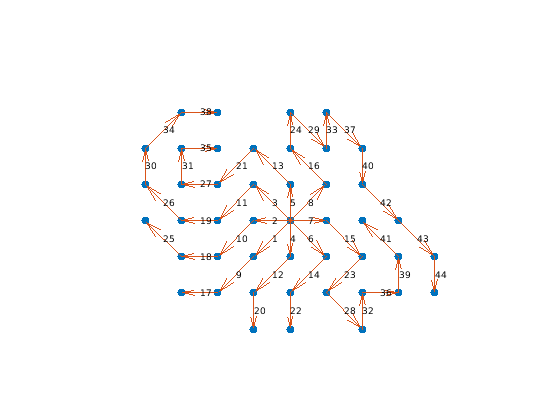

load('../Data/BSGrid_200_1152_200_0.mat');
figure;
scatter(bsGridIndex(:,1), bsGridIndex(:,2),'filled');
hold on;
load('../Data/Topology_200_1152_45.mat');
numRelays = 1152;
bsLinks = bsLinks - numRelays + 1;
pX = bsGridIndex(bsLinks(:,1),1);
pY = bsGridIndex(bsLinks(:,1),2);
vX = bsGridIndex(bsLinks(:,2),1) - bsGridIndex(bsLinks(:,1),1);
vY = bsGridIndex(bsLinks(:,2),2) - bsGridIndex(bsLinks(:,1),2);
quiver(pX,pY,vX,vY);
for i = 1:length(bsLinks(:,1))
    txt = num2str(i);
    tX = (bsGridIndex(bsLinks(i,2),1) + bsGridIndex(bsLinks(i,1),1))/2;
    tY = (bsGridIndex(bsLinks(i,2),2) + bsGridIndex(bsLinks(i,1),2))/2;
    text(tX, tY, txt, 'FontSize', 7);
end
axis off;
daspect([1 1 1]);